# HW3

clear
clc
close all
show_every_step = false;
show_background = false;

## setup the scene

dimY = 663; dimX = 1000;
grid = boolean(zeros(dimX,dimY)); % in mm
grid = drawSq(grid, 1,1,dimX, dimY,1);

debugPlot(show_every_step, show_background, grid);

put some circles

grid = boolean(grid + putObstacle(dimX, dimY, 308, 264, 60));
grid = boolean(grid + putObstacle(dimX, dimY, 267, 539, 60));
grid = boolean(grid + putObstacle(dimX, dimY, 684, 279, 60));
grid = boolean(grid + putObstacle(dimX, dimY, 902, 100, 60));

debugPlot(show_every_step, show_background, grid);

## Put a robot

robot_position_vector = [115 106];
robot_direction = [0];
grid = boolean(grid + putRobot(grid, robot_position_vector, robot_direction));



## try to move the robot

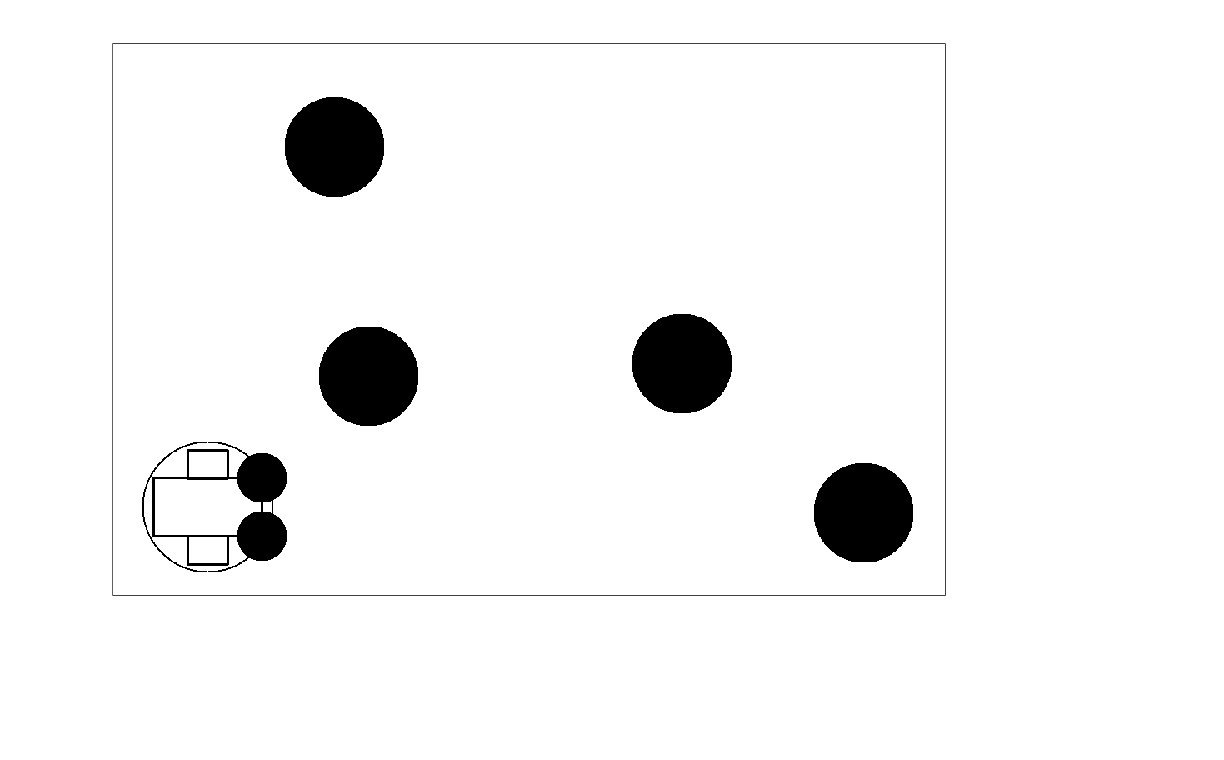

for step = 1:45
    figure(1)
    showmap(show_background, grid);
    pause(0.1)
    robot_direction = robot_direction+1;
    drawnow
end

## show

% showmap(show_background, grid);